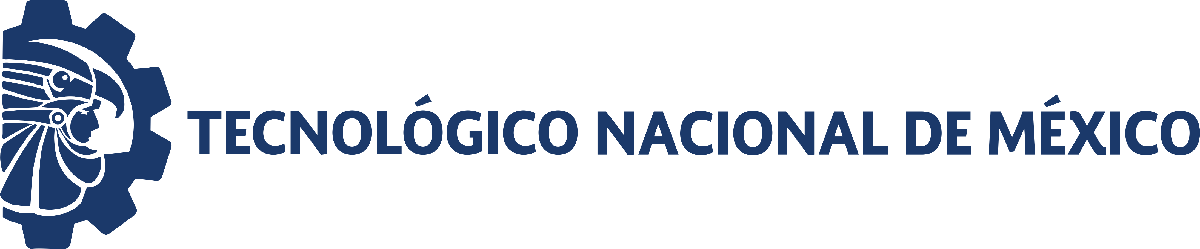                                 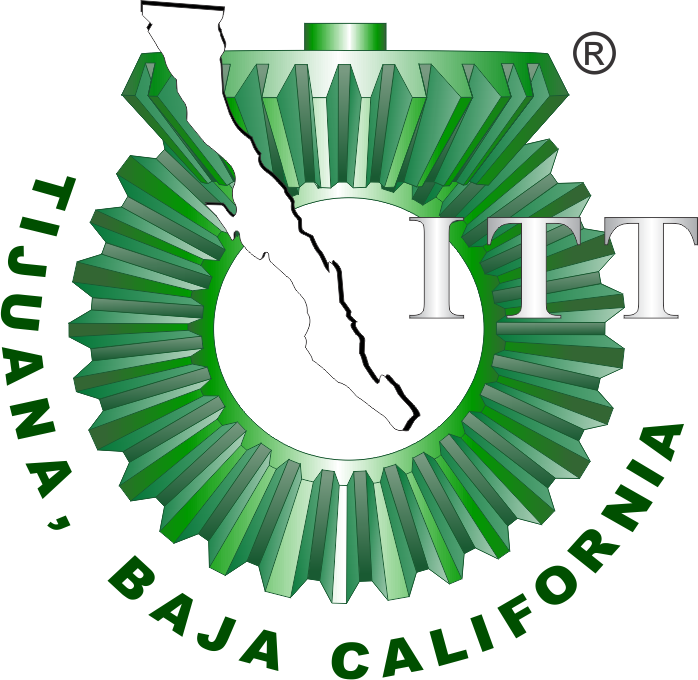

# Práctica 3: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

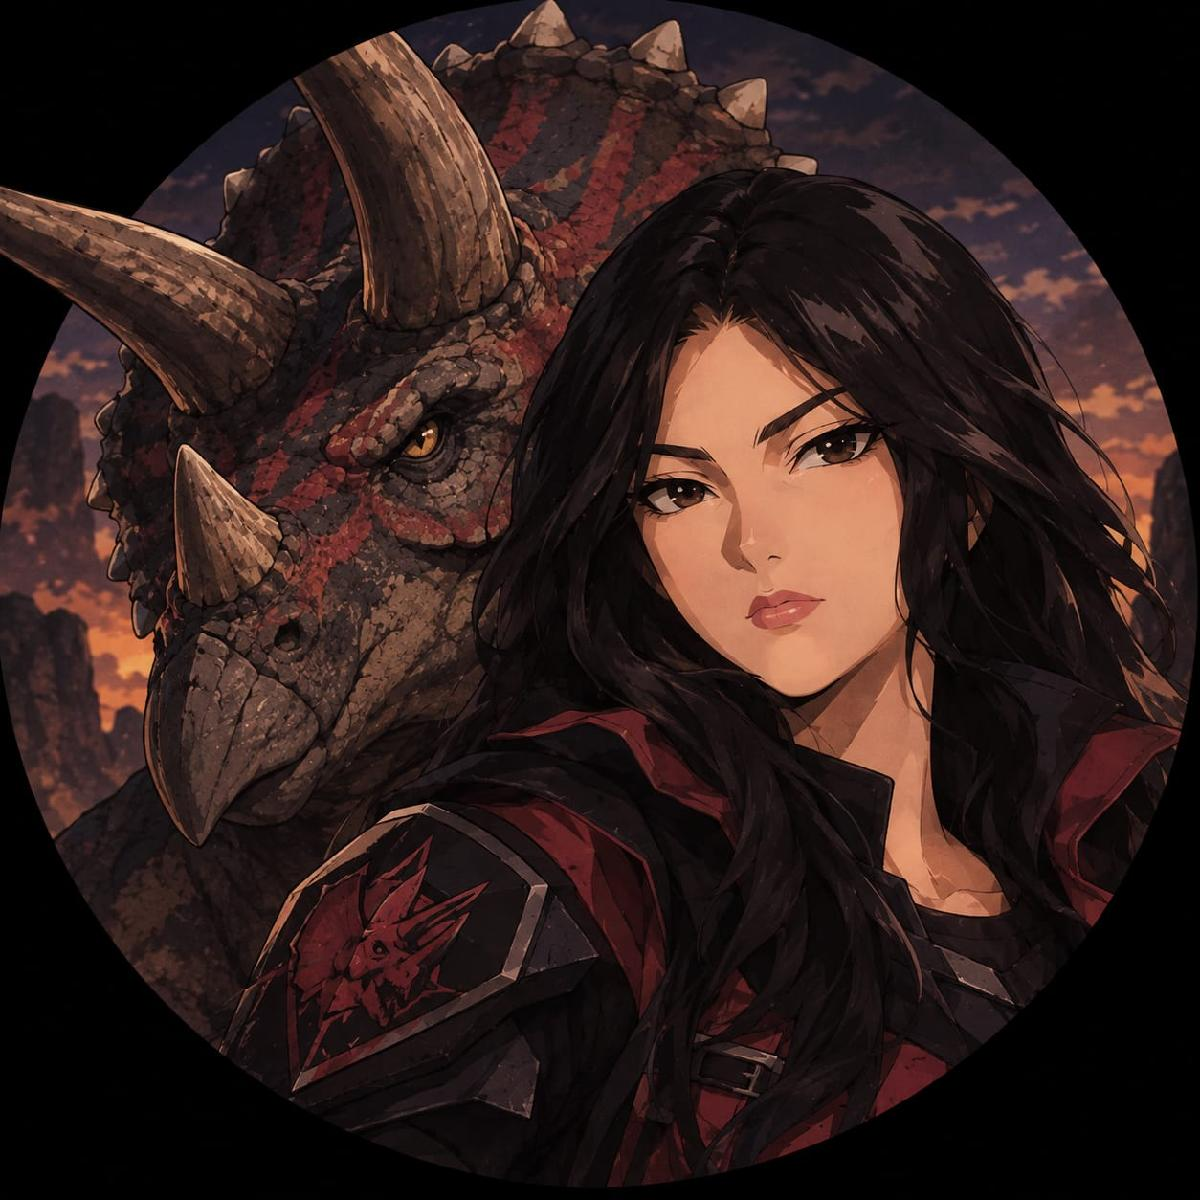

Nombre del alumno: Kenia Yasdit Contreras Jiménez

Número de control: 23212188

Correo institucional: l23212188**@tijuana.tecnm.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema3')                
parameters.StopTime = '15';           
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('sistema3',parameters);         

## `Respuestas: F(t), Control, Caso y PID`

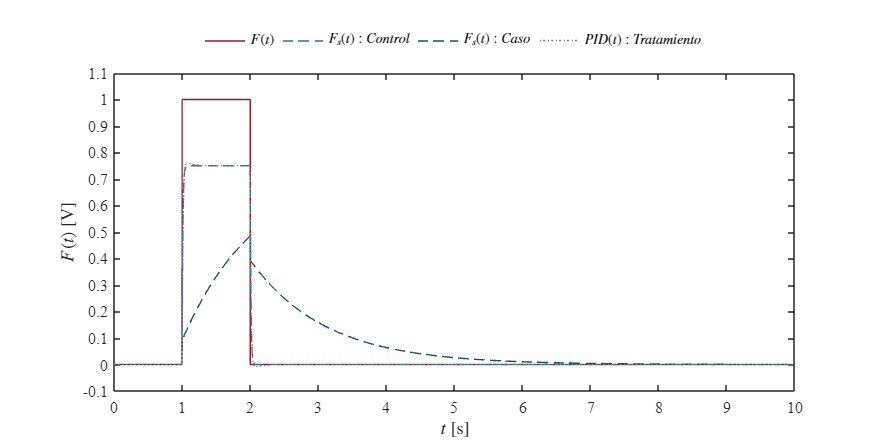

plotsignals(x.t,x.F,x.Fs1,x.FsC,x.PID,'Simulink')

## Modelo de EDOs

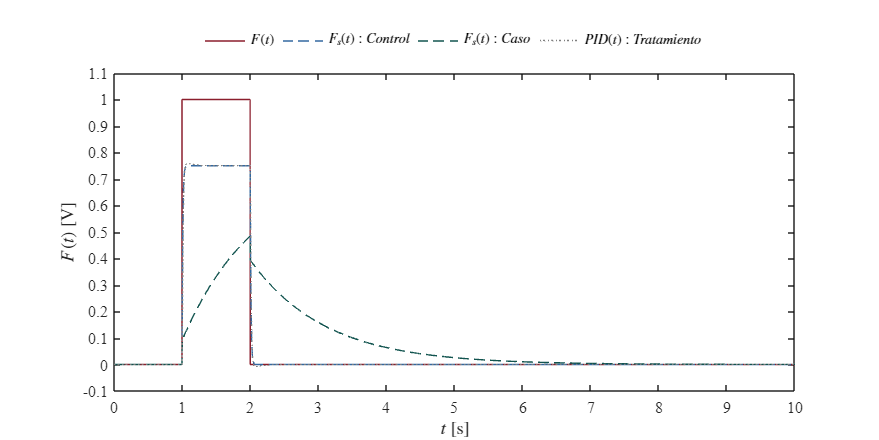

dt = 1e-3;
t = (0:dt:10)';
F = zeros(length(t),1); F(1/dt:2/dt) = 1;
PID = interp1(x.t,x.PID,t,'previous');

par_control = [0.25,10e-6,100e-6,100];
par_caso  = [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control,F,t);
Fs_caso = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID,'EDOsys')

function Fs = musculoesqueletico(par,F,t)
    alpha = par(1); Cs = par(2); Cp = par(3); R = par(4); dt = t(2);
    n = round(t(end)/dt);
    x = zeros(length(t),1); x(1) = 0;
    Fs = zeros(length(t),1); Fs(1) = 0;    
    for i = 1 :n
        x(i+1) = x(i) + ((F(i)-x(i))/(R*(Cp+Cs)))*dt; %EDO
        Fs(i+1) = Cs*F(i)/(Cp+Cs) + (1 - alpha - Cs/(Cp+Cs))*x(i); %Función
    end
end



## Respuestas de simulación

function plotsignals(t,F,Fs1,Fs2,PID,name)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])
set(gca,'fontname','times new roman','fontsize',12)
hold on; grid off; box on;
clr1 = [139, 30, 45] / 255;
clr2 = [51, 104, 160] / 255;
clr3 = [18, 84, 79] / 255;
clr4 = [0.5, 0.5, 0.5];
order = [clr1;clr2;clr3;clr4]; colororder(order)

plot(t,F,'-','LineWidth',0.25,'Color',clr1)  %F(t)
plot(t,Fs1,'--','LineWidth',0.25,'Color',clr2)  %Control
plot(t,Fs2,'--','LineWidth',0.25,'Color',clr3)  %Caso
plot(t,PID,':','LineWidth',1,'Color',clr4)     %PID Tratamiento

L = legend('$F(t)$','$F_s(t):Control$','$F_s(t):Caso$','$PID(t):Tratamiento$');
set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')

xlabel('$t$ [s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')

xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
exportgraphics(gcf,['matlab_', name, '.pdf'],'ContentType','vector')
end